# POST-PROCESSING OF IMAGES FROM PLANAR KIRIGAMI EXPERIMENTS

"Continuum Field Theory for the Deformations of Planar Kirigami" Yue Zheng, Imtiar Niloy, Paolo Celli, Ian Tobasco, and Paul Plucinsky Phys. Rev. Lett. 128, 208003 ? Published 20 May 2022

% Code created on July 2021

close all;
clear all;
clc;

## INPUT NEEDED -- CHOICE OF SPECIMEN/EXPERIMENTAL RESULT TO ANALYZE

%filename='061521_AnIsoLRSidesCenterPull_v2_7cm'; para = [3 100]; % for Hyperbolic Pulling
filename='061521_AnIsoLRSidesCenterPull_0cm'; para = [3 100]; % for Hyperbolic Pulling

%filename='060821_IsoLRSidesCenterPull_8cm'; para = [0 42]; % for Elliptic Pulling
%filename='060821_IsoLRSidesCenterPull_0cm'; para = [0 42]; % for Elliptic Pulling

% filename = '070121_ForcedIntoAnnulus_Hyperbolic'; para = [0 42]; % for Hyperbolic Annulus

% filename = '070121_ForcedIntoAnnulus_Elliptic'; para = [0 42]; % for Elliptic Annulus

%filename = '063021_Mixed_LRSidesCenterPull_6'; para = [0 100]; %Test for mixed

## IMAGE READ

I = imread([filename,'.tif']);

BW = imbinarize(I);
BW = logical(1 - BW);

stats = regionprops('table',BW,'Centroid','Area','MajorAxisLength','MinorAxisLength','Orientation');
Cent = stats.Centroid;
Area = stats.Area;
Maax = stats.MajorAxisLength;
Miax = stats.MinorAxisLength;
Orit = stats.Orientation;
Orit = -Orit/180*pi;

hinge = para(1);
Maax = Maax + hinge;
Maax(Maax>para(2))=para(2);

Angle=atan(Miax./Maax);
%xi_in = 0.32 %0.219; %For mixed kirigami
xi_in = 0.06; %0.06; %For hyperbolic kirigami
%xi_in = 0.11; %0.09; %For auxetic kirigami
Angle = Angle-xi_in;

## INPUT NEEDED -- CHOOSE SLIT THRESHOLDS

Slit=(Area>20 & Area<1000); % for Hyperbolic Pulling

%Slit=(Area>20 & Area<3200); % for Elliptic Pulling

% Slit=(Area>20 & Area<1000); % for Hyperbolic Annulus

% Slit=(Area>20 & Area<2000); % for Elliptic Annulus

%Slit=(Area>200 & Area<1700) & Maax < 60;% for Mixed Pulling

## PLOTS

disp(Cent(Slit,1))

   1.0e+03 *

    0.8967
    0.8941
    0.9037
    0.8989
    0.9012
    0.9018
    0.9041
    0.9047
    0.9193
    0.9086
    0.9065
    0.9084
    0.9270
    0.9101
    0.9124
    0.9138
    0.9137
    0.9166
    0.9174
    0.9159
    0.9357
    0.9193
    0.9215
    0.9427
    0.9434
    0.9412
    0.9509
    0.9535
    0.9510
    0.9518
    0.9523
    0.9536
    0.9540
    0.9567
    0.9584
    0.9607
    0.9604
    0.9639
    0.9636
    0.9644
    0.9639
    0.9648
    0.9829
    0.9674
    0.9836
    0.9878
    0.9907
    0.9934
    0.9944
    0.9953
    0.9928
    0.9958
    0.9970
    0.9980
    0.9998
    0.9997
    1.0010
    1.0025
    1.0037
    1.0056
    1.0068
    1.0073
    1.0097
    1.0102
    1.0117
    1.0099
    1.0123
    1.0135
    1.0150
    1.0136
    1.0334
    1.0383
    1.0370
    1.0401
    1.0429
    1.0420
    1.0451
    1.0467
    1.0486
    1.0502
    1.0479
    1.0501
    1.0520
    1.0517
    1.0526
    1.0544
    1.0569
    1.0568
    1.0585
    1.0

disp(Cent(Slit,2))

   1.0e+03 *

    1.3526
    1.6384
    0.6811
    1.4476
    1.2555
    1.1604
    0.9686
    0.7777
    1.7819
    0.5855
    1.5908
    0.4907
    1.4952
    1.4002
    1.3052
    1.1120
    1.2081
    1.0166
    0.8252
    0.9210
    0.3472
    0.6340
    0.4435
    1.1121
    1.0167
    1.5912
    0.4439
    0.6342
    0.8258
    0.9214
    1.7343
    0.7293
    1.6393
    1.4484
    1.3531
    1.1607
    1.2561
    0.8739
    0.9692
    1.0643
    0.7784
    0.6822
    0.3959
    0.5868
    1.7347
    1.6396
    1.4489
    1.2565
    1.1611
    0.9695
    1.3536
    1.0647
    0.7787
    0.8744
    0.6824
    1.7825
    1.6875
    1.5916
    1.4961
    1.4006
    1.3047
    1.2090
    1.1130
    1.0177
    0.8258
    0.9222
    0.6349
    0.5392
    0.3484
    0.4437
    1.7826
    1.4964
    1.5918
    1.3051
    1.1131
    1.2096
    0.9226
    1.7359
    0.5395
    0.4445
    1.6402
    1.5444
    1.4492
    1.3531
    1.2573
    1.1617
    0.8739
    0.9703
    1.0660
    0.6

disp(Angle(Slit))

    0.0630
    0.1541
    0.0598
    0.2144
    0.1479
    0.1713
    0.1573
    0.1397
   -0.0145
    0.1791
    0.1188
    0.1309
   -0.0164
    0.1147
    0.0916
    0.1159
    0.0941
    0.0727
    0.1032
    0.1216
   -0.0068
    0.1109
    0.0960
    0.0026
    0.0272
    0.0865
    0.0285
    0.1067
    0.1237
    0.1409
    0.1073
    0.1706
    0.1078
    0.1116
    0.1146
    0.1173
    0.1081
    0.0707
    0.0857
    0.0749
    0.1499
    0.1315
   -0.0177
    0.0690
    0.0732
    0.1126
    0.0893
    0.0893
    0.0638
    0.0951
    0.1278
    0.1017
    0.0892
    0.1625
    0.1164
    0.0873
    0.0779
    0.0995
    0.1011
    0.0900
    0.0958
    0.0976
    0.0625
    0.0881
    0.0735
    0.1316
    0.1035
    0.0904
    0.0925
    0.1398
    0.1347
    0.1286
    0.1382
    0.0679
    0.0978
    0.1123
    0.1231
    0.0892
    0.1690
    0.1437
    0.1417
    0.0935
    0.0863
    0.1777
    0.1500
    0.1072
    0.1126
    0.1051
    0.0463
    0.0856
    0.1132

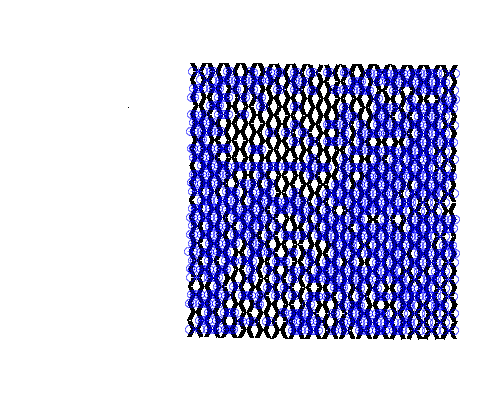


figure;
imshow(BW);
hold on;
plot(Cent(Slit,1),Cent(Slit,2),'b*')

plot([Cent(Slit,1)+Maax(Slit)/2.*cos(Orit(Slit)) Cent(Slit,1)-Maax(Slit)/2.*cos(Orit(Slit))]...
    ,[Cent(Slit,2)+Maax(Slit)/2.*sin(Orit(Slit)) Cent(Slit,2)-Maax(Slit)/2.*sin(Orit(Slit))],'bo')



figure;
subimage(BW);
hold on;
scatter2 = scatter(Cent(Slit,1),Cent(Slit,2),100,Angle(Slit),'filled')

scatter2 =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: 'flat'
          LineWidth: 0.5000
              XData: [896.7179 894.1250 903.6875 898.9000 901.1935 901.7667 904.0870 904.7037 919.2500 908.6296 906.5455 908.3913 926.9697 910.0909 912.3929 913.8276 913.7200 916.6486 917.3793 915.9091 935.6893 919.3333 921.5161 942.7500 943.3830 … ]
              YData: [1.3526e+03 1.6384e+03 681.1250 1.4476e+03 1.2555e+03 1.1604e+03 968.5652 777.6667 1.7819e+03 585.5185 1.5908e+03 490.7391 1.4952e+03 1.4002e+03 1.3052e+03 1.1120e+03 1.2081e+03 1.0166e+03 825.2414 921 347.2039 633.9583 443.5161 … ]
           SizeData: 100
              CData: [605×1 double]

  Show 

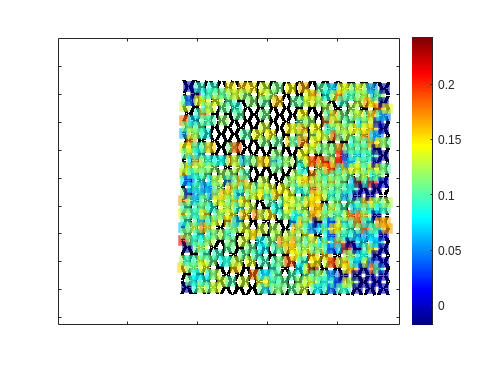

colormap jet;
scatter2.MarkerFaceAlpha = .6;
scatter2.Marker = 's';
set(gca,'XtickLabel',[],'YtickLabel',[])
colorbar